# Assignment 1

Load in data downloaded for problem 1

data = load("../HMP_Dataset/Climb_stairs/Accelerometer-2011-03-24-10-24-39-climb_stairs-f1.txt");

## Data loaded and now we plot the original data as problem 2

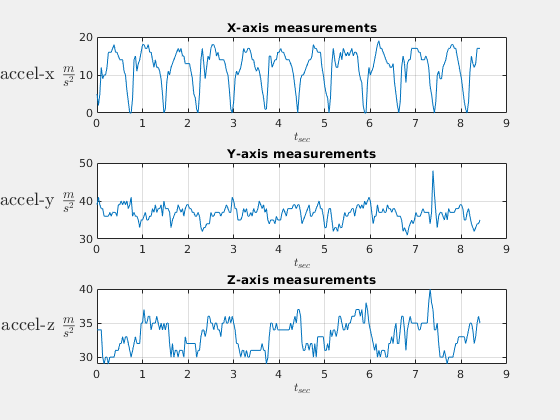

% loading in the data from the csv matrix
x = data(:,1);
y = data(:,2);
z = data(:,3);
% plotting before conversions
plot_data(x,y,z,'Before conversion');

## define a function for conversion and apply it for problem 3

functions for plotting and conversion are at the bottom of the file

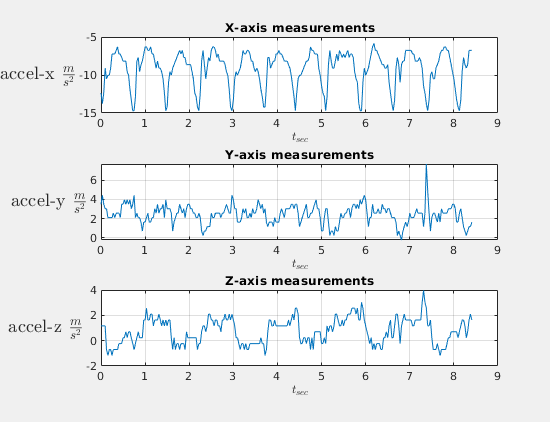

% converting data using the conversion equations from manual.txt
x = convert(data(:,1));
y = convert(data(:,2));
z = convert(data(:,3));

%plotting the data after conversion
plot_data(x,y,z,'After conversion');

## Next is to set up the sampling for problem 4

need a cosine signal cos(2*pi*f*t) w/ f = 30Hz

run the code below and then view the video made by combining frames. This will not work in html, but is visible when run in the mlx format

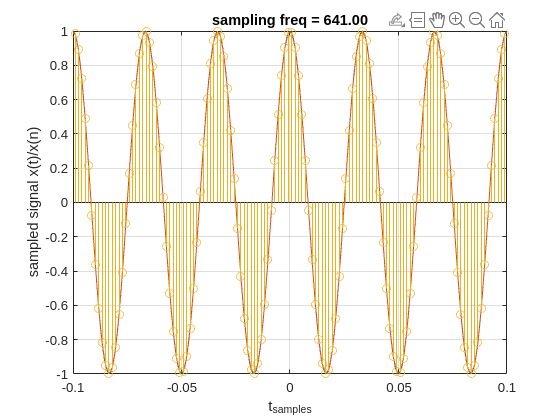

% creating a signal with many samples to compare the samples to
t = linspace(-0.5,0.5,1000);
c = (@(f,t) cos(2*pi*f*t));
% setting a freq of 30hz for the 
Fs = 30;
figure
% sampling for 1-640Hz as an example
for i = 1:641
    plot(t,c(Fs,t)) % 30 Hz signal
    interval = linspace(-.5,.5,i+1); % interval samples
    f= [interval;c(Fs,interval)];
    hold on
    % sampled plot and stem
    plot(f(1,:),f(2,:))
    stem(f(1,:),f(2,:))
    title(sprintf("sampling freq = %.2f",i))
    ylabel 'sampled signal x(t)/x(n)'
    xlabel 't_{samples}'
    grid on
    % although we could look at the signal from -.5 to .5, looking at the
    % interval from -.1 .1 makes the plots more digestable
    xlim([-.1 .1])
    pause(.01)
    hold off
end

As we can see, the signal from 30Hz is aliased and appears as a constant. The signal with 50Hz is better, but it still does not appear as good as it could be. With a rate higher than 60, we get some artifacts in the signal, but we are able to get a decent representation of the signal now. The nature of the samples being better using 60 or above can be seen with the rate of 60. The signal is sampled twice per period and we can recover the oscillations in the output.

## Setting up the frequencies asked for in problem 4

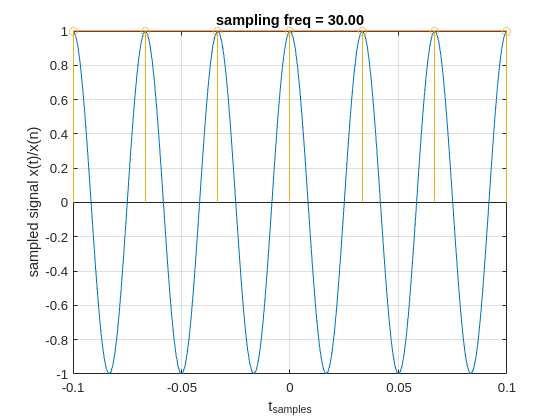

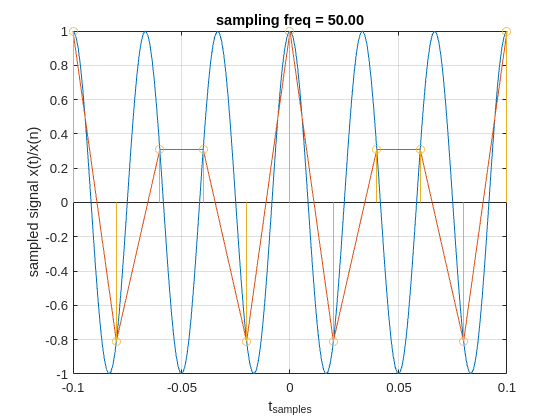

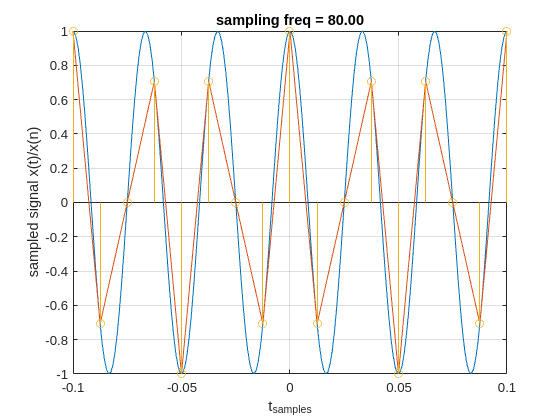

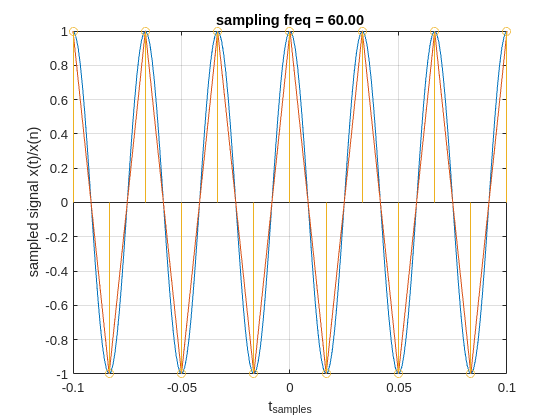

% creating a signal with many samples to compare the samples to
t = linspace(-0.5,0.5,1000);
% setting a freq of 30hz for the 
Fs = 30;
% sampling for 30,50,and 80 Hz
for i = [30 50 80 60]
    figure
    plot(t,c(Fs,t)) % 30 Hz signal
    interval = linspace(-.5,.5,i+1); % interval samples
    f= [interval;c(Fs,interval)];
    hold on
    % sampled plot and stem
    plot(f(1,:),f(2,:))
    stem(f(1,:),f(2,:))
    title(sprintf("sampling freq = %.2f",i))
    ylabel 'sampled signal x(t)/x(n)'
    xlabel 't_{samples}'
    grid on
    % although we could look at the signal from -.5 to .5, looking at the
    % interval from -.1 .1 makes the plots more digestable
    xlim([-.1 .1])
    pause(.01)
    hold off
end

## Combined signal for part 5

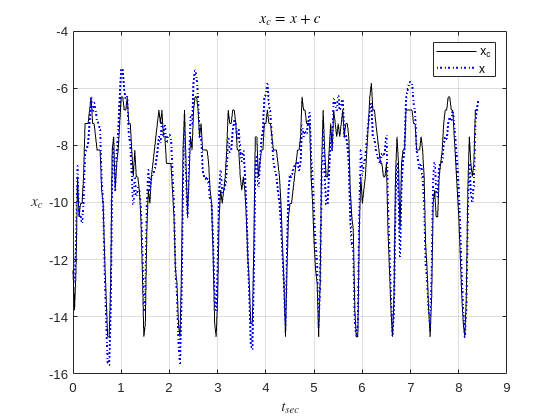

Fs = 32;
N = length(x)-1;
t_span = N*(1/Fs);
t = 0:1/Fs:t_span;

Fs = 30;
figure
% sampling for 30,50,and 80 Hz
plot(t,x','k')
hold on
plot(t,x'+c(Fs,t),'b:',LineWidth=1.5) % 30 Hz signal
title("$x_c = x + c$",Interpreter="latex")
xlabel('$t_{sec}$',Interpreter='latex')
ylabel('$x_c$',Interpreter='latex',Rotation=0)
legend('x_c','x')
grid on
hold off

## sampling code to show a similar effect as the example.

This samples more and more values from the signal x to show that we could get a much better approximation of the signal the more we sample per second. Best results start to appear above 2x the sampling rate of the data from the archive, and get better as the number of samples increases. Note* Again, this will not work in html, but is visible when run in the mlx format

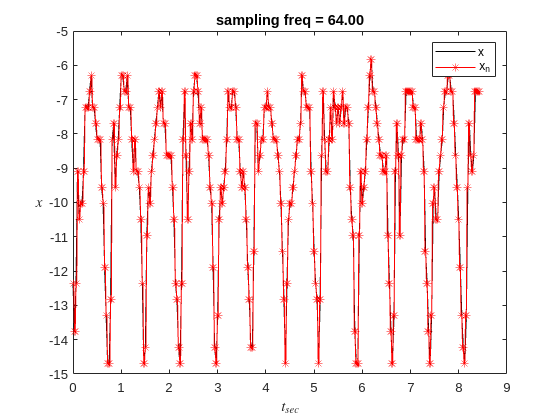


% their periods are 1/freq
Ts = freq.^(-1);
n_s = floor(t_span./Ts)+1;
% example sampling freq of data we have
Fs = 32;
% the span of time/period gives the number of samples we have in the data.
N = length(x);
t_span = N*(1/Fs);
t = 0:t_span/N:(t_span-1/Fs);
freq = 2:1:64;
figure
for i = freq
    t_s = 0:t_span/n_s(i-1):(t_span - 1/n_s(i-1));
    abs_diff = abs(t(:) - t_s(:).');
    % Find the index of the minimum absolute difference for each element in vec2
    [~, closest_indices] = min(abs_diff, [], 1);
    plot(t,x,'k')    
    hold on 
    plot(t_s,x(closest_indices),'-*r')
    plot_title = sprintf('sampling freq = %.2f',i);
    title(plot_title)  
    xlabel('$t_{sec}$',Interpreter='latex')
    ylabel('$x$',Interpreter='latex',Rotation=0)
    legend('x','x_n')
    hold off
    pause(.01)
end

according to the Readme in the repo, there is a defined max and min From the file: Acceleration data recorded in the dataset are coded according to the following mapping: [0; +63] = [-1.5g; +1.5g] the following function achieves this using the specified expression:

function a = convert(data)
g = 9.8; % as in m/s^2
a = -1.5*g + 3*g*(data/63);
end

% creates a plot with subregions for each of the three values of interest
% also includes a name for the figure to tell what set is plotted
function plot_data(x,y,z,name)
Fs = 32;
t = 0:(1/Fs):((length(x)-1)*(1/Fs));
figure(Visible="on",Name=name)
subplot(3,1,1)
plot(t,x)
title 'X-axis measurements'
xlabel('$t_{sec}$',Interpreter='latex')
ylabel("accel-x $\frac{m}{s^2}$",Interpreter="latex",Rotation=0,FontSize=14)
grid on
subplot(3,1,2)
plot(t,y)
title 'Y-axis measurements'
xlabel('$t_{sec}$',Interpreter='latex')
ylabel("accel-y $\frac{m}{s^2}$",Interpreter="latex",Rotation=0,FontSize=14)
grid on
subplot(3,1,3)
plot(t,z)
title 'Z-axis measurements'
xlabel('$t_{sec}$',Interpreter='latex')
ylabel ("accel-z $\frac{m}{s^2}$",Interpreter="latex",Rotation=0,FontSize=14)
grid on

end